clear;clc;
% 生成时间序列
t = -100:0.01:100;
v = 100;
ratio = 2;

% 找到最大速度和最小速度随时间变化的趋势，以及最大速度和对应的时刻
[max_speed, min_speed, max_speed_value, max_speed_time] = find_speed_range(t, v, ratio);

% 打印最大速度及其对应的时刻
fprintf('最大速度: %.2f\n', max_speed_value);

最大速度: 160.48


fprintf('最小速度: %.2f\n', min(min_speed));

最小速度: 53.97


fprintf('最大速度对应的时刻: %.2f\n', max_speed_time);

最大速度对应的时刻: 14.48


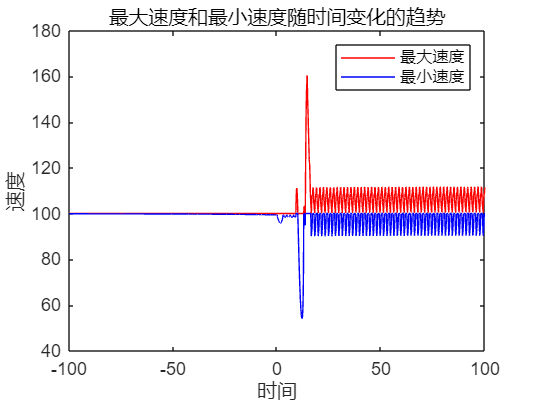


% 绘制最大速度和最小速度随时间变化的图
figure;
plot(t, max_speed, 'r', 'DisplayName', '最大速度');
hold on;
plot(t, min_speed, 'b', 'DisplayName', '最小速度');
xlabel('时间');
ylabel('速度');
title('最大速度和最小速度随时间变化的趋势');
legend show;

function [max_speed, min_speed, max_speed_value, max_speed_time] = find_speed_range(t, v, ratio)
    % 初始化最大速度和最小速度数组
    max_speed = -inf * ones(size(t));
    min_speed = inf * ones(size(t));
    max_speed_value = -inf;
    max_speed_time = NaN;

    % 遍历所有时间点
    for i = 1:length(t)
        % 计算 s 和 theta_list
        s = t(i) * v;
        theta_list = calculate_angles_mix(s, ratio);
        
        % 计算速度
        speed_list = calculate_speeds_mix(theta_list, ratio);
        
        % 更新最大速度和最小速度
        max_speed(i) = max(speed_list);
        min_speed(i) = min(speed_list);
        
        % 更新最大速度值和对应的时刻
        if max_speed(i) > max_speed_value
            max_speed_value = max_speed(i);
            max_speed_time = t(i);
        end
    end
end